# Create and Configure AUTOSAR Adaptive Software Component

Create an AUTOSAR adaptive software component model from an algorithm model.

AUTOSAR Blockset software supports AUTomotive Open System ARchitecture (AUTOSAR), an open and standardized automotive software architecture. Automobile manufacturers, suppliers, and tool developers jointly develop AUTOSAR components. To develop AUTOSAR adaptive components in Simulink, follow this general workflow:

- Create a Simulink representation of an AUTOSAR adaptive component.

- Develop the component by refining the AUTOSAR configuration and creating algorithmic model content.

- Generate ARXML descriptions and algorithmic C++ code for testing in Simulink or integration into an AUTOSAR run-time environment. (AUTOSAR code generation requires Simulink Coder and Embedded Coder.)

## Create AUTOSAR Adaptive Software Component in Simulink

To create an initial Simulink representation of an AUTOSAR adaptive software component, you take one of these actions:

- Create an AUTOSAR adaptive software component using an existing Simulink model.

- Import an AUTOSAR adaptive software component description from ARXML files into a new Simulink model. (See example [Import AUTOSAR Adaptive Components to Simulink](docid:autosar_ug.mw_225a4289-71a6-4708-9117-187a08ea82ce).)

To create an AUTOSAR adaptive software component using an existing model, first open a Simulink component model for which an AUTOSAR software component is not mapped. This example uses AUTOSAR example model `LaneGuidance`.

open_system('LaneGuidance'); 

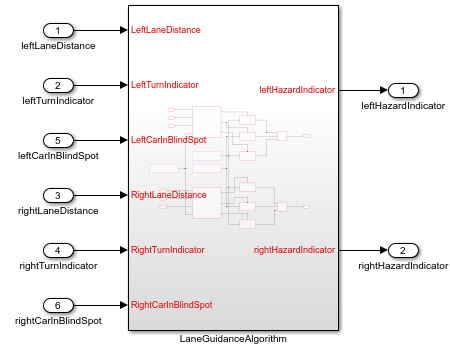

In the model window, on the **Modeling** tab, select **Model Settings**. In the Configuration Parameters dialog box, **Code Generation** pane, set the system target file to `autosar_adaptive.tlc`. Click **OK**.

At the top level of the model, set up event-based communication. An AUTOSAR adaptive software component provides and consumes services. Each component contains:

- An algorithm that performs tasks in response to received events

- Required and provided ports, each associated with a service interface

- Service interfaces, with associated events and associated namespaces

AUTOSAR Blockset provides [Event Receive](docid:autosar_ref.bvczlz2-ercv) and [Event Send](docid:autosar_ref.mw_588ad55b-5421-4926-a0f0-261491da6d33) blocks to make the necessary event and signal connections.

- After each root inport, add an Event Receive block, which converts an input event to a signal while preserving the signal values and data type.

- Before each root outport, add an Event Send block, which converts an input signal to an event while preserving the signal values and data type.

(To expedite the block insertion, you can copy the event blocks from AUTOSAR example model `autosar_LaneGuidance`.)

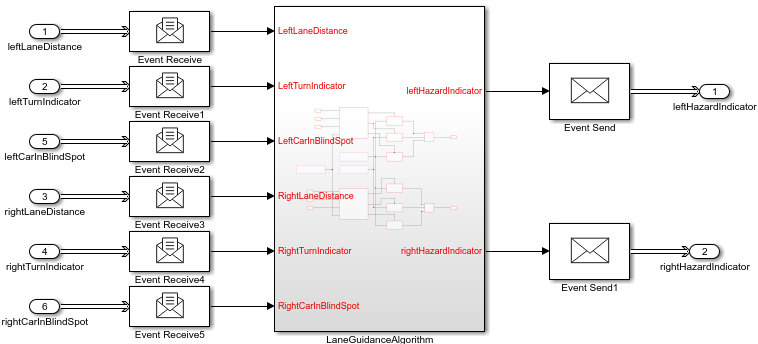

To configure the model as a mapped AUTOSAR adaptive software component, open the AUTOSAR Component Quick Start. On the **Apps** tab, click **AUTOSAR Component Designer**. The AUTOSAR Component Quick Start opens.

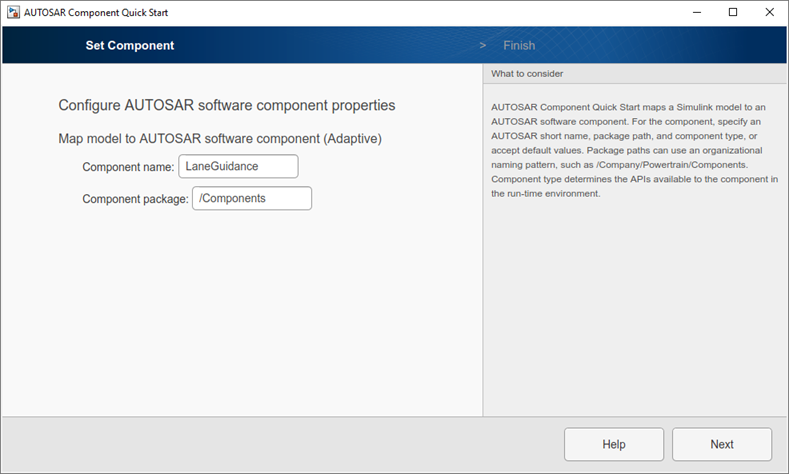

To configure the model for AUTOSAR adaptive software component development, work through the quick-start procedure. This example accepts default settings for the options in the Quick Start **Set Component** pane.

In the **Finish** pane, when you click **Finish**, your model opens in the AUTOSAR code perspective.

## Configure AUTOSAR Adaptive Software Component in Simulink

The AUTOSAR code perspective displays your model, and directly below the model, the Code Mappings editor.

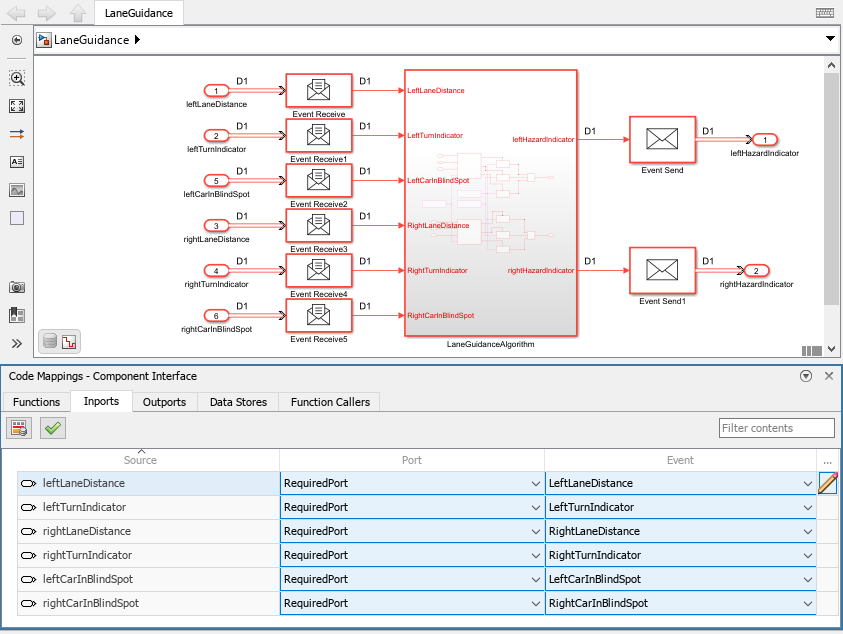

Next you use the Code Mappings editor and the AUTOSAR Dictionary to further develop the AUTOSAR adaptive component.

The Code Mappings editor displays model inports and outports. Use the editor to map Simulink inports and outports to AUTOSAR required ports and provided ports (defined in the AUTOSAR standard) from a Simulink model perspective.

Open each Code Mapping tab and examine the mapped model elements. To modify the AUTOSAR mapping for an element, select an element and modify its associated properties. When you select an element, it is highlighted in the model.

To configure the AUTOSAR properties of the mapped AUTOSAR adaptive software component, open the AUTOSAR Dictionary. In the Code Mappings editor, click the AUTOSAR Dictionary button, which is the leftmost icon. The AUTOSAR Dictionary opens in the AUTOSAR view that corresponds to the Simulink element that you last selected and mapped in the Code Mappings editor. If you selected and mapped a Simulink inport, the dictionary opens in RequiredPorts view and displays the AUTOSAR port to which you mapped the inport.

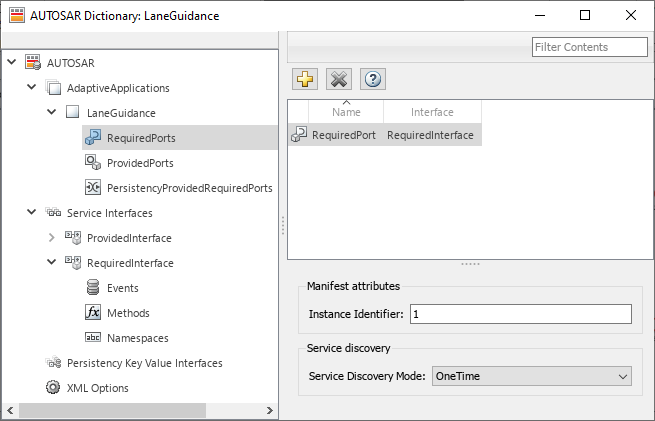

The AUTOSAR Dictionary displays the mapped AUTOSAR adaptive component and its elements, communication interfaces, and XML options. Use the dictionary to configure AUTOSAR elements and properties from an AUTOSAR component perspective.

Open each node and examine its AUTOSAR elements. To modify an AUTOSAR element, select an element and modify its associated properties. AUTOSAR XML and AUTOSAR-compliant C code generated from the model reflect your modifications.

## Generate C++ Code and ARXML Descriptions (Embedded Coder)

If you have Simulink Coder and Embedded Coder software, you can build the AUTOSAR adaptive model. Building the AUTOSAR model generates AUTOSAR-compliant C++ code and exports AUTOSAR XML (ARXML) descriptions. In the model window, press **Ctrl+B** or, on the **AUTOSAR** tab, click **Generate Code**.

When the build completes, a code generation report opens. Examine the report. Verify that your Code Mappings editor and AUTOSAR Dictionary changes are reflected in the C++ code and ARXML descriptions. For example, use the **Find** field to search for the names of the Simulink model elements and AUTOSAR component elements that you modified.

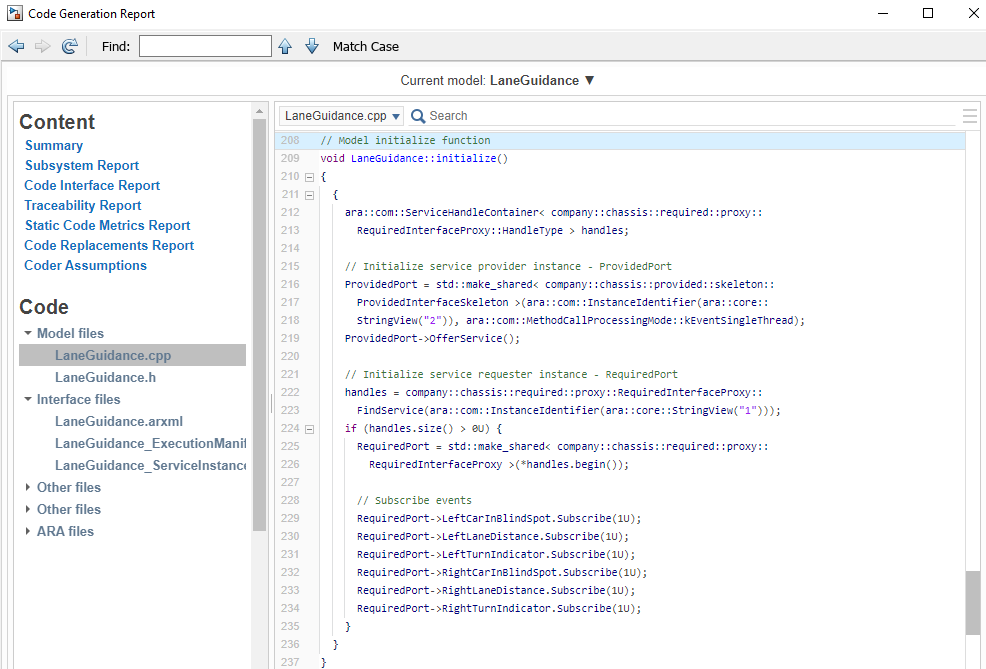

## Related Links

- [AUTOSAR Component Configuration](docid:autosar_ug.bt2wgsd)

- [Code Generation](docid:autosar_doccenter.mw_e655a5c6-8aec-4d28-914b-088b3c4ac00c) (Adaptive Platform)

- [AUTOSAR Blockset](docid:autosar_doccenter.index)

*Copyright 2018-2020 The MathWorks, Inc.*